% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 9;
avgNum = 3;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

#### Blood Plasma Well Trial 2024-07-25, D223 150μL Sample

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-25/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

% well 1 data 2024-07-25

file_name = "Blood_Plasma1(40x,495mW,Well1)_2000_30_2024-07-25-14.05.15.270.csv";
file_path = data_path+file_name;
blood_1_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well1)_2000_30_2024-07-25-14.06.46.857.csv";
file_path = strcat(data_path,file_name);
blood_2_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well1)_2000_30_2024-07-25-14.08.19.973.csv";
file_path = strcat(data_path,file_name);
blood_3_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well1)_2000_30_2024-07-25-14.09.54.200.csv";
file_path = strcat(data_path,file_name);
blood_4_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well1)_2000_30_2024-07-25-14.11.27.703.csv";
file_path = strcat(data_path,file_name);
blood_5_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well1)_2000_30_2024-07-25-14.13.11.530.csv";
file_path = strcat(data_path,file_name);
blood_6_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well1)_2000_30_2024-07-25-14.14.49.133.csv";
file_path = strcat(data_path,file_name);
blood_7_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well1)_2000_30_2024-07-25-14.16.26.297.csv";
file_path = strcat(data_path,file_name);
blood_8_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well1)_2000_30_2024-07-25-14.18.03.237.csv";
file_path = strcat(data_path,file_name);
blood_9_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well1)_2000_30_2024-07-25-14.19.38.440.csv";
file_path = strcat(data_path,file_name);
blood_10_1 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_250_2024-07-25-13.25.42.187.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_250_2024-07-25-13.35.03.900.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_250_2024-07-25-13.39.18.243.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1_1(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;

wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];

blood_1_1(:, blood_1_1(1, :) <= t1) = [];
blood_1_1(:, blood_1_1(1, :) >= t2) = [];
blood_2_1(:, blood_2_1(1, :) <= t1) = [];
blood_2_1(:, blood_2_1(1, :) >= t2) = [];
blood_3_1(:, blood_3_1(1, :) <= t1) = [];
blood_3_1(:, blood_3_1(1, :) >= t2) = [];
blood_4_1(:, blood_4_1(1, :) <= t1) = [];
blood_4_1(:, blood_4_1(1, :) >= t2) = [];
blood_5_1(:, blood_5_1(1, :) <= t1) = [];
blood_5_1(:, blood_5_1(1, :) >= t2) = [];
blood_6_1(:, blood_6_1(1, :) <= t1) = [];
blood_6_1(:, blood_6_1(1, :) >= t2) = [];
blood_7_1(:, blood_7_1(1, :) <= t1) = [];
blood_7_1(:, blood_7_1(1, :) >= t2) = [];
blood_8_1(:, blood_8_1(1, :) <= t1) = [];
blood_8_1(:, blood_8_1(1, :) >= t2) = [];
blood_9_1(:, blood_9_1(1, :) <= t1) = [];
blood_9_1(:, blood_9_1(1, :) >= t2) = [];
blood_10_1(:, blood_10_1(1, :) <= t1) = [];
blood_10_1(:, blood_10_1(1, :) >= t2) = [];

shifts = wavenumber;

blood1_1 = blood_1_1(2:end, :);
blood2_1 = blood_2_1(2:end, :);
blood3_1 = blood_3_1(2:end, :);
blood4_1 = blood_4_1(2:end, :);
blood5_1 = blood_5_1(2:end, :);
blood6_1 = blood_6_1(2:end, :);
blood7_1 = blood_7_1(2:end, :);
blood8_1 = blood_8_1(2:end, :);
blood9_1 = blood_9_1(2:end, :);
blood10_1 = blood_10_1(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];
% Plotting unprocessed data

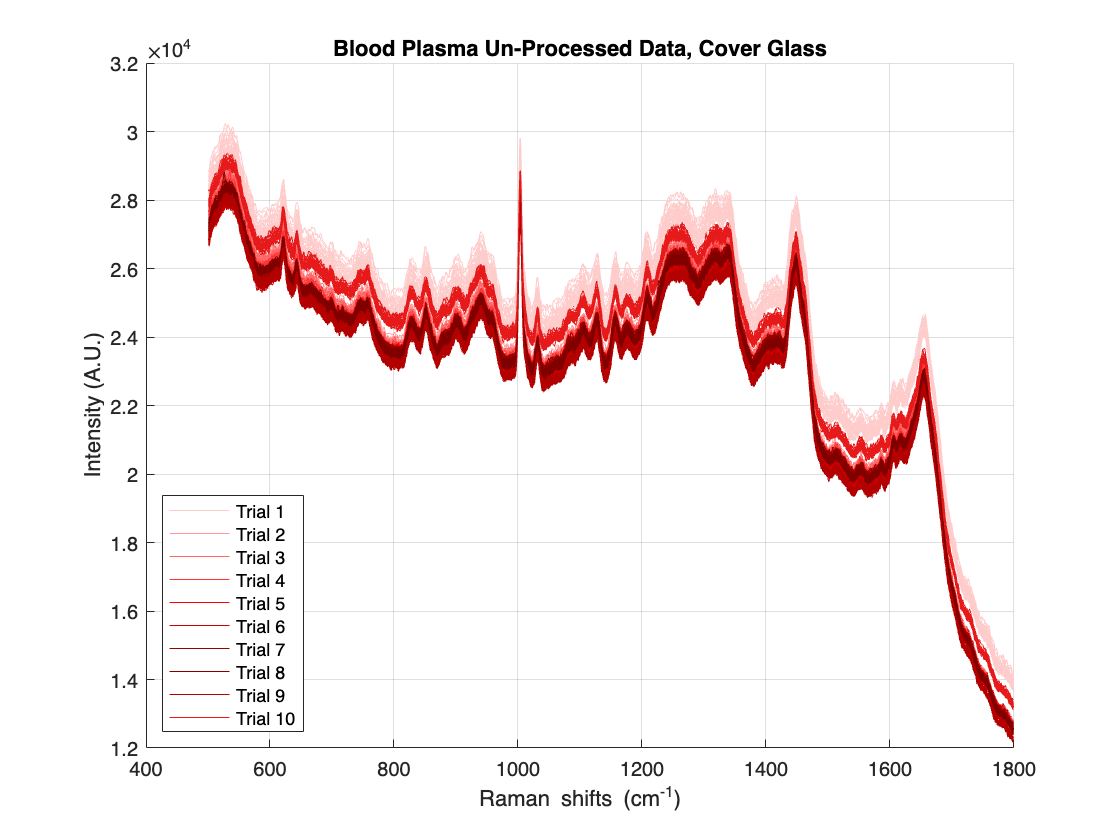

figure;
hold on;
grid on;
plot(wavenumber, blood1_1(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1(1,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1(1,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, blood1_1(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1(2:end,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1(2:end,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;

% Preprocessing the data

pro_blood1_1 = apply(blood1_1, [6,1,10,11,8,2,5,6,7]);
pro_blood2_1 = apply(blood2_1, [6,1,10,11,8,2,5,6,7]);
pro_blood3_1 = apply(blood3_1, [6,1,10,11,8,2,5,6,7]);
pro_blood4_1 = apply(blood4_1, [6,1,10,11,8,2,5,6,7]);
pro_blood5_1 = apply(blood5_1, [6,1,10,11,8,2,5,6,7]);
pro_blood6_1 = apply(blood6_1, [6,1,10,11,8,2,5,6,7]);
pro_blood7_1 = apply(blood7_1, [6,1,10,11,8,2,5,6,7]);
pro_blood8_1 = apply(blood8_1, [6,1,10,11,8,2,5,6,7]);
pro_blood9_1 = apply(blood9_1, [6,1,10,11,8,2,5,6,7]);
pro_blood10_1 = apply(blood10_1, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood_1 = [blood1_1;blood2_1;blood3_1;blood4_1;blood5_1;blood6_1;blood7_1;blood8_1;blood9_1;blood10_1];
pro_blood_1 = apply(blood_1, [6,1,10,11,8,2,5,6,7]);

#### Blood Plasma Well Trial 2024-07-16, D223 50μL Sample

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-16/";


% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Blood_Plasma(40x,495mW,CG)_2500_24_2024-07-16-17.30.45.390.csv";
file_path = data_path+file_name;
blood_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,CG)_2500_24_2024-07-16-17.34.17.403.csv";
file_path = strcat(data_path,file_name);
blood_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,CG)_2500_24_2024-07-16-17.36.52.490.csv";
file_path = strcat(data_path,file_name);
blood_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,CG)_2500_24_2024-07-16-17.39.44.847.csv";
file_path = strcat(data_path,file_name);
blood_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,CG)_2500_24_2024-07-16-17.42.28.170.csv";
file_path = strcat(data_path,file_name);
blood_5 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,CG)_2500_24_2024-07-16-17.45.13.607.csv";
file_path = strcat(data_path,file_name);
blood_6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,CG)_2500_24_2024-07-16-17.47.59.203.csv";
file_path = strcat(data_path,file_name);
blood_7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,CG)_2500_24_2024-07-16-17.50.32.927.csv";
file_path = strcat(data_path,file_name);
blood_8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,CG)_2000_24_2024-07-16-17.53.48.730.csv";
file_path = strcat(data_path,file_name);
blood_9 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,CG)_2000_24_2024-07-16-17.55.52.113.csv";
file_path = strcat(data_path,file_name);
blood_10 = csvread(file_path, numMetadataRows, 0);

nist1 = readmatrix('Data/NIST_0823_120523_2023-05-12-08.23.54.csv');
NISTspectrum = [blood_6(1, 1:3101) ; nist1(23:end, :)];

file_name = "Polystyrene(40x,495mW)_70_100_2024-07-16-15.45.20.927.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_60_100_2024-07-16-15.41.03.040.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
blood_1(:, blood_1(1, :) <= t1) = [];
blood_1(:, blood_1(1, :) >= t2) = [];
blood_2(:, blood_2(1, :) <= t1) = [];
blood_2(:, blood_2(1, :) >= t2) = [];
blood_3(:, blood_3(1, :) <= t1) = [];
blood_3(:, blood_3(1, :) >= t2) = [];
blood_4(:, blood_4(1, :) <= t1) = [];
blood_4(:, blood_4(1, :) >= t2) = [];
blood_5(:, blood_5(1, :) <= t1) = [];
blood_5(:, blood_5(1, :) >= t2) = [];
blood_6(:, blood_6(1, :) <= t1) = [];
blood_6(:, blood_6(1, :) >= t2) = [];
blood_7(:, blood_7(1, :) <= t1) = [];
blood_7(:, blood_7(1, :) >= t2) = [];
blood_8(:, blood_8(1, :) <= t1) = [];
blood_8(:, blood_8(1, :) >= t2) = [];
blood_9(:, blood_9(1, :) <= t1) = [];
blood_9(:, blood_9(1, :) >= t2) = [];
blood_10(:, blood_10(1, :) <= t1) = [];
blood_10(:, blood_10(1, :) >= t2) = [];

shifts = wavenumber;

blood1 = blood_1(2:end, :);
blood2 = blood_2(2:end, :);
blood3 = blood_3(2:end, :);
blood4 = blood_4(2:end, :);
blood5 = blood_5(2:end, :);
blood6 = blood_6(2:end, :);
blood7 = blood_7(2:end, :);
blood8 = blood_8(2:end, :);
blood9 = blood_9(2:end, :);
blood10 = blood_10(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

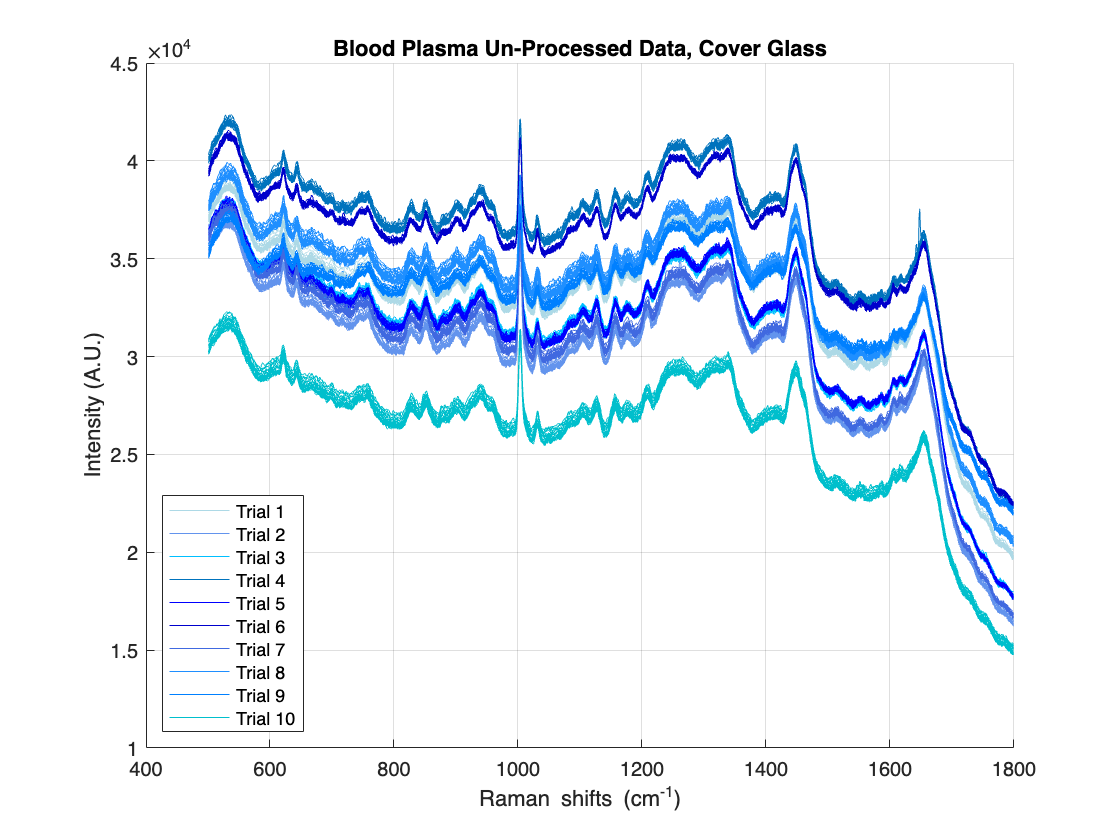

% Plotting unprocessed data

figure;
hold on;
grid on;

% Different shades of blue for the plots
plot(wavenumber, blood1(1,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(1,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(1,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(1,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(1,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(1,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(1,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8(1,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(1,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(1,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

plot(wavenumber, blood1(2:end,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(2:end,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(2:end,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(2:end,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(2:end,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(2:end,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(2:end,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8(2:end,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(2:end,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(2:end,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;

% Preprocessing the data

pro_blood1 = apply(blood1, [6,1,10,11,8,2,5,6,7]);
pro_blood2 = apply(blood2, [6,1,10,11,8,2,5,6,7]);
pro_blood3 = apply(blood3, [6,1,10,11,8,2,5,6,7]);
pro_blood4 = apply(blood4, [6,1,10,11,8,2,5,6,7]);
pro_blood5 = apply(blood5, [6,1,10,11,8,2,5,6,7]);
pro_blood6 = apply(blood6, [6,1,10,11,8,2,5,6,7]);
pro_blood7 = apply(blood7, [6,1,10,11,8,2,5,6,7]);
pro_blood8 = apply(blood8, [6,1,10,11,8,2,5,6,7]);
pro_blood9 = apply(blood9, [6,1,10,11,8,2,5,6,7]);
pro_blood10 = apply(blood10, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood = [blood1;blood2;blood3;blood4;blood5;blood6;blood7;blood8;blood9;blood10];
pro_blood = apply(blood, [6,1,10,8,2,5,6,7]);

#### Calculating Statistical Data for Both Trials

## 2024-07-16

% Data for 1003 cm^-1 peak
Trial1 = pro_blood1(:, 503);
Trial2 = pro_blood2(:, 503);
Trial3 = pro_blood3(:, 503);
Trial4 = pro_blood4(:, 503);
Trial5 = pro_blood5(:, 503);
Trial6 = pro_blood6(:, 503);
Trial7 = pro_blood7(:, 503);
Trial8 = pro_blood8(:, 503);
Trial9 = pro_blood9(:, 503);
Trial10 = pro_blood10(:, 503);

% Calculate means
av_Trial1 = mean(Trial1);
av_Trial2 = mean(Trial2);
av_Trial3 = mean(Trial3);
av_Trial4 = mean(Trial4);
av_Trial5 = mean(Trial5);
av_Trial6 = mean(Trial6);
av_Trial7 = mean(Trial7);
av_Trial8 = mean(Trial8);
av_Trial9 = mean(Trial9);
av_Trial10 = mean(Trial10);

% Calculate standard deviations
std_Trial1 = std(Trial1);
std_Trial2 = std(Trial2);
std_Trial3 = std(Trial3);
std_Trial4 = std(Trial4);
std_Trial5 = std(Trial5);
std_Trial6 = std(Trial6);
std_Trial7 = std(Trial7);
std_Trial8 = std(Trial8);
std_Trial9 = std(Trial9);
std_Trial10 = std(Trial10);

% Number of spectra in each collection
n_Trial1 = size(Trial1, 1);
n_Trial2 = size(Trial2, 1);
n_Trial3 = size(Trial3, 1);
n_Trial4 = size(Trial4, 1);
n_Trial5 = size(Trial5, 1);
n_Trial6 = size(Trial6, 1);
n_Trial7 = size(Trial7, 1);
n_Trial8 = size(Trial8, 1);
n_Trial9 = size(Trial9, 1);
n_Trial10 = size(Trial10, 1);

% Perform t-tests between pairs
[t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2] = perform_ttest(av_Trial1, av_Trial2, std_Trial1, std_Trial2, n_Trial1, n_Trial2);
[t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3] = perform_ttest(av_Trial1, av_Trial3, std_Trial1, std_Trial3, n_Trial1, n_Trial3);
[t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4] = perform_ttest(av_Trial1, av_Trial4, std_Trial1, std_Trial4, n_Trial1, n_Trial4);
[t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5] = perform_ttest(av_Trial1, av_Trial5, std_Trial1, std_Trial5, n_Trial1, n_Trial5);
[t_Trial1_Trial6, p_Trial1_Trial6, df_Trial1_Trial6] = perform_ttest(av_Trial1, av_Trial6, std_Trial1, std_Trial6, n_Trial1, n_Trial6);
[t_Trial1_Trial7, p_Trial1_Trial7, df_Trial1_Trial7] = perform_ttest(av_Trial1, av_Trial7, std_Trial1, std_Trial7, n_Trial1, n_Trial7);
[t_Trial1_Trial8, p_Trial1_Trial8, df_Trial1_Trial8] = perform_ttest(av_Trial1, av_Trial8, std_Trial1, std_Trial8, n_Trial1, n_Trial8);
[t_Trial1_Trial9, p_Trial1_Trial9, df_Trial1_Trial9] = perform_ttest(av_Trial1, av_Trial9, std_Trial1, std_Trial9, n_Trial1, n_Trial9);
[t_Trial1_Trial10, p_Trial1_Trial10, df_Trial1_Trial10] = perform_ttest(av_Trial1, av_Trial10, std_Trial1, std_Trial10, n_Trial1, n_Trial10);
[t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3] = perform_ttest(av_Trial2, av_Trial3, std_Trial2, std_Trial3, n_Trial2, n_Trial3);
[t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4] = perform_ttest(av_Trial2, av_Trial4, std_Trial2, std_Trial4, n_Trial2, n_Trial4);
[t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5] = perform_ttest(av_Trial2, av_Trial5, std_Trial2, std_Trial5, n_Trial2, n_Trial5);
[t_Trial2_Trial6, p_Trial2_Trial6, df_Trial2_Trial6] = perform_ttest(av_Trial2, av_Trial6, std_Trial2, std_Trial6, n_Trial2, n_Trial6);
[t_Trial2_Trial7, p_Trial2_Trial7, df_Trial2_Trial7] = perform_ttest(av_Trial2, av_Trial7, std_Trial2, std_Trial7, n_Trial2, n_Trial7);
[t_Trial2_Trial8, p_Trial2_Trial8, df_Trial2_Trial8] = perform_ttest(av_Trial2, av_Trial8, std_Trial2, std_Trial8, n_Trial2, n_Trial8);
[t_Trial2_Trial9, p_Trial2_Trial9, df_Trial2_Trial9] = perform_ttest(av_Trial2, av_Trial9, std_Trial2, std_Trial9, n_Trial2, n_Trial9);
[t_Trial2_Trial10, p_Trial2_Trial10, df_Trial2_Trial10] = perform_ttest(av_Trial2, av_Trial10, std_Trial2, std_Trial10, n_Trial2, n_Trial10);
[t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4] = perform_ttest(av_Trial3, av_Trial4, std_Trial3, std_Trial4, n_Trial3, n_Trial4);
[t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5] = perform_ttest(av_Trial3, av_Trial5, std_Trial3, std_Trial5, n_Trial3, n_Trial5);
[t_Trial3_Trial6, p_Trial3_Trial6, df_Trial3_Trial6] = perform_ttest(av_Trial3, av_Trial6, std_Trial3, std_Trial6, n_Trial3, n_Trial6);
[t_Trial3_Trial7, p_Trial3_Trial7, df_Trial3_Trial7] = perform_ttest(av_Trial3, av_Trial7, std_Trial3, std_Trial7, n_Trial3, n_Trial7);
[t_Trial3_Trial8, p_Trial3_Trial8, df_Trial3_Trial8] = perform_ttest(av_Trial3, av_Trial8, std_Trial3, std_Trial8, n_Trial3, n_Trial8);
[t_Trial3_Trial9, p_Trial3_Trial9, df_Trial3_Trial9] = perform_ttest(av_Trial3, av_Trial9, std_Trial3, std_Trial9, n_Trial3, n_Trial9);
[t_Trial3_Trial10, p_Trial3_Trial10, df_Trial3_Trial10] = perform_ttest(av_Trial3, av_Trial10, std_Trial3, std_Trial10, n_Trial3, n_Trial10);
[t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5] = perform_ttest(av_Trial4, av_Trial5, std_Trial4, std_Trial5, n_Trial4, n_Trial5);
[t_Trial4_Trial6, p_Trial4_Trial6, df_Trial4_Trial6] = perform_ttest(av_Trial4, av_Trial6, std_Trial4, std_Trial6, n_Trial4, n_Trial6);
[t_Trial4_Trial7, p_Trial4_Trial7, df_Trial4_Trial7] = perform_ttest(av_Trial4, av_Trial7, std_Trial4, std_Trial7, n_Trial4, n_Trial7);
[t_Trial4_Trial8, p_Trial4_Trial8, df_Trial4_Trial8] = perform_ttest(av_Trial4, av_Trial8, std_Trial4, std_Trial8, n_Trial4, n_Trial8);
[t_Trial4_Trial9, p_Trial4_Trial9, df_Trial4_Trial9] = perform_ttest(av_Trial4, av_Trial9, std_Trial4, std_Trial9, n_Trial4, n_Trial9);
[t_Trial4_Trial10, p_Trial4_Trial10, df_Trial4_Trial10] = perform_ttest(av_Trial4, av_Trial10, std_Trial4, std_Trial10, n_Trial4, n_Trial10);
[t_Trial5_Trial6, p_Trial5_Trial6, df_Trial5_Trial6] = perform_ttest(av_Trial5, av_Trial6, std_Trial5, std_Trial6, n_Trial5, n_Trial6);
[t_Trial5_Trial7, p_Trial5_Trial7, df_Trial5_Trial7] = perform_ttest(av_Trial5, av_Trial7, std_Trial5, std_Trial7, n_Trial5, n_Trial7);
[t_Trial5_Trial8, p_Trial5_Trial8, df_Trial5_Trial8] = perform_ttest(av_Trial5, av_Trial8, std_Trial5, std_Trial8, n_Trial5, n_Trial8);
[t_Trial5_Trial9, p_Trial5_Trial9, df_Trial5_Trial9] = perform_ttest(av_Trial5, av_Trial9, std_Trial5, std_Trial9, n_Trial5, n_Trial9);
[t_Trial5_Trial10, p_Trial5_Trial10, df_Trial5_Trial10] = perform_ttest(av_Trial5, av_Trial10, std_Trial5, std_Trial10, n_Trial5, n_Trial10);
[t_Trial6_Trial7, p_Trial6_Trial7, df_Trial6_Trial7] = perform_ttest(av_Trial6, av_Trial7, std_Trial6, std_Trial7, n_Trial6, n_Trial7);
[t_Trial6_Trial8, p_Trial6_Trial8, df_Trial6_Trial8] = perform_ttest(av_Trial6, av_Trial8, std_Trial6, std_Trial8, n_Trial6, n_Trial8);
[t_Trial6_Trial9, p_Trial6_Trial9, df_Trial6_Trial9] = perform_ttest(av_Trial6, av_Trial9, std_Trial6, std_Trial9, n_Trial6, n_Trial9);
[t_Trial6_Trial10, p_Trial6_Trial10, df_Trial6_Trial10] = perform_ttest(av_Trial6, av_Trial10, std_Trial6, std_Trial10, n_Trial6, n_Trial10);
[t_Trial7_Trial8, p_Trial7_Trial8, df_Trial7_Trial8] = perform_ttest(av_Trial7, av_Trial8, std_Trial7, std_Trial8, n_Trial7, n_Trial8);
[t_Trial7_Trial9, p_Trial7_Trial9, df_Trial7_Trial9] = perform_ttest(av_Trial7, av_Trial9, std_Trial7, std_Trial9, n_Trial7, n_Trial9);
[t_Trial7_Trial10, p_Trial7_Trial10, df_Trial7_Trial10] = perform_ttest(av_Trial7, av_Trial10, std_Trial7, std_Trial10, n_Trial7, n_Trial10);
[t_Trial8_Trial9, p_Trial8_Trial9, df_Trial8_Trial9] = perform_ttest(av_Trial8, av_Trial9, std_Trial8, std_Trial9, n_Trial8, n_Trial9);
[t_Trial8_Trial10, p_Trial8_Trial10, df_Trial8_Trial10] = perform_ttest(av_Trial8, av_Trial10, std_Trial8, std_Trial10, n_Trial8, n_Trial10);
[t_Trial9_Trial10, p_Trial9_Trial10, df_Trial9_Trial10] = perform_ttest(av_Trial9, av_Trial10, std_Trial9, std_Trial10, n_Trial9, n_Trial10);

% Display results
fprintf('t-test and p values for pairwise comparisons at 1003 cm^-1 peak:\n');

t-test and p values for pairwise comparisons at 1003 cm^-1 peak:


fprintf('Trial 1 vs Trial 2: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2);

Trial 1 vs Trial 2: t = 5.5776, p = 0.0001, df = 12.0000


fprintf('Trial 1 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3);

Trial 1 vs Trial 3: t = -2.2243, p = 0.0452, df = 12.5057


fprintf('Trial 1 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4);

Trial 1 vs Trial 4: t = -3.0202, p = 0.0110, df = 11.5817


fprintf('Trial 1 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5);

Trial 1 vs Trial 5: t = 1.4088, p = 0.1824, df = 12.9990


fprintf('Trial 1 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial6, p_Trial1_Trial6, df_Trial1_Trial6);

Trial 1 vs Trial 6: t = -5.5754, p = 0.0001, df = 11.4653


fprintf('Trial 1 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial7, p_Trial1_Trial7, df_Trial1_Trial7);

Trial 1 vs Trial 7: t = -4.5852, p = 0.0009, df = 10.2426


fprintf('Trial 1 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial8, p_Trial1_Trial8, df_Trial1_Trial8);

Trial 1 vs Trial 8: t = -11.1716, p = 0.0000, df = 12.4663


fprintf('Trial 1 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial9, p_Trial1_Trial9, df_Trial1_Trial9);

Trial 1 vs Trial 9: t = -18.4156, p = 0.0000, df = 12.0794


fprintf('Trial 1 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial10, p_Trial1_Trial10, df_Trial1_Trial10);

Trial 1 vs Trial 10: t = -7.2386, p = 0.0000, df = 9.2472


fprintf('Trial 2 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3);

Trial 2 vs Trial 3: t = -8.1322, p = 0.0000, df = 12.5108


fprintf('Trial 2 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4);

Trial 2 vs Trial 4: t = -8.0407, p = 0.0000, df = 11.5773


fprintf('Trial 2 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5);

Trial 2 vs Trial 5: t = -3.9232, p = 0.0017, df = 12.9987


fprintf('Trial 2 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial6, p_Trial2_Trial6, df_Trial2_Trial6);

Trial 2 vs Trial 6: t = -10.5160, p = 0.0000, df = 11.4604


fprintf('Trial 2 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial7, p_Trial2_Trial7, df_Trial2_Trial7);

Trial 2 vs Trial 7: t = -8.8546, p = 0.0000, df = 10.2361


fprintf('Trial 2 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial8, p_Trial2_Trial8, df_Trial2_Trial8);

Trial 2 vs Trial 8: t = -15.8973, p = 0.0000, df = 12.4613


fprintf('Trial 2 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial9, p_Trial2_Trial9, df_Trial2_Trial9);

Trial 2 vs Trial 9: t = -22.9105, p = 0.0000, df = 12.0735


fprintf('Trial 2 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial10, p_Trial2_Trial10, df_Trial2_Trial10);

Trial 2 vs Trial 10: t = -10.9991, p = 0.0000, df = 9.2413


fprintf('Trial 3 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4);

Trial 3 vs Trial 4: t = -1.1828, p = 0.2611, df = 11.3417


fprintf('Trial 3 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5);

Trial 3 vs Trial 5: t = 3.5999, p = 0.0031, df = 13.4355


fprintf('Trial 3 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial6, p_Trial3_Trial6, df_Trial3_Trial6);

Trial 3 vs Trial 6: t = -3.8838, p = 0.0025, df = 11.1543


fprintf('Trial 3 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial7, p_Trial3_Trial7, df_Trial3_Trial7);

Trial 3 vs Trial 7: t = -3.0766, p = 0.0122, df = 9.6553


fprintf('Trial 3 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial8, p_Trial3_Trial8, df_Trial3_Trial8);

Trial 3 vs Trial 8: t = -9.7801, p = 0.0000, df = 12.1427


fprintf('Trial 3 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial9, p_Trial3_Trial9, df_Trial3_Trial9);

Trial 3 vs Trial 9: t = -17.3437, p = 0.0000, df = 11.6069


fprintf('Trial 3 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial10, p_Trial3_Trial10, df_Trial3_Trial10);

Trial 3 vs Trial 10: t = -5.9713, p = 0.0002, df = 8.6878


fprintf('Trial 4 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5);

Trial 4 vs Trial 5: t = 4.1899, p = 0.0011, df = 12.5768


fprintf('Trial 4 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial6, p_Trial4_Trial6, df_Trial4_Trial6);

Trial 4 vs Trial 6: t = -2.3931, p = 0.0340, df = 11.9912


fprintf('Trial 4 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial7, p_Trial4_Trial7, df_Trial4_Trial7);

Trial 4 vs Trial 7: t = -1.8910, p = 0.0845, df = 11.3292


fprintf('Trial 4 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial8, p_Trial4_Trial8, df_Trial4_Trial8);

Trial 4 vs Trial 8: t = -7.7075, p = 0.0000, df = 12.9939


fprintf('Trial 4 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial9, p_Trial4_Trial9, df_Trial4_Trial9);

Trial 4 vs Trial 9: t = -14.6412, p = 0.0000, df = 12.8785


fprintf('Trial 4 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial10, p_Trial4_Trial10, df_Trial4_Trial10);

Trial 4 vs Trial 10: t = -4.7307, p = 0.0007, df = 10.3683


fprintf('Trial 5 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial6, p_Trial5_Trial6, df_Trial5_Trial6);

Trial 5 vs Trial 6: t = -6.6401, p = 0.0000, df = 12.4501


fprintf('Trial 5 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial7, p_Trial5_Trial7, df_Trial5_Trial7);

Trial 5 vs Trial 7: t = -5.5621, p = 0.0002, df = 11.0611


fprintf('Trial 5 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial8, p_Trial5_Trial8, df_Trial5_Trial8);

Trial 5 vs Trial 8: t = -12.0213, p = 0.0000, df = 13.4494


fprintf('Trial 5 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial9, p_Trial5_Trial9, df_Trial5_Trial9);

Trial 5 vs Trial 9: t = -19.0315, p = 0.0000, df = 13.0179


fprintf('Trial 5 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial10, p_Trial5_Trial10, df_Trial5_Trial10);

Trial 5 vs Trial 10: t = -8.0618, p = 0.0000, df = 9.8882


fprintf('Trial 6 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial7, p_Trial6_Trial7, df_Trial6_Trial7);

Trial 6 vs Trial 7: t = 0.2171, p = 0.8319, df = 11.4568


fprintf('Trial 6 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial8, p_Trial6_Trial8, df_Trial6_Trial8);

Trial 6 vs Trial 8: t = -5.3375, p = 0.0001, df = 12.9996


fprintf('Trial 6 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial9, p_Trial6_Trial9, df_Trial6_Trial9);

Trial 6 vs Trial 9: t = -12.2956, p = 0.0000, df = 12.9353


fprintf('Trial 6 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial10, p_Trial6_Trial10, df_Trial6_Trial10);

Trial 6 vs Trial 10: t = -2.8227, p = 0.0172, df = 10.5297


fprintf('Trial 7 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial7_Trial8, p_Trial7_Trial8, df_Trial7_Trial8);

Trial 7 vs Trial 8: t = -4.9689, p = 0.0003, df = 12.3683


fprintf('Trial 7 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial7_Trial9, p_Trial7_Trial9, df_Trial7_Trial9);

Trial 7 vs Trial 9: t = -11.2576, p = 0.0000, df = 12.7139


fprintf('Trial 7 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial7_Trial10, p_Trial7_Trial10, df_Trial7_Trial10);

Trial 7 vs Trial 10: t = -2.7841, p = 0.0169, df = 11.6639


fprintf('Trial 8 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial8_Trial9, p_Trial8_Trial9, df_Trial8_Trial9);

Trial 8 vs Trial 9: t = -6.9553, p = 0.0000, df = 13.9184


fprintf('Trial 8 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial8_Trial10, p_Trial8_Trial10, df_Trial8_Trial10);

Trial 8 vs Trial 10: t = 1.5250, p = 0.1548, df = 11.2958


fprintf('Trial 9 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial9_Trial10, p_Trial9_Trial10, df_Trial9_Trial10);

Trial 9 vs Trial 10: t = 7.3291, p = 0.0000, df = 11.8108


% Calculate average variance and average T-test value for each well test

% Calculate variances for each trial
var_Trial1 = var(Trial1);
var_Trial2 = var(Trial2);
var_Trial3 = var(Trial3);
var_Trial4 = var(Trial4);
var_Trial5 = var(Trial5);
var_Trial6 = var(Trial6);
var_Trial7 = var(Trial7);
var_Trial8 = var(Trial8);
var_Trial9 = var(Trial9);
var_Trial10 = var(Trial10);

% Calculate average variance
avg_var1 = mean([var_Trial1, var_Trial2, var_Trial3, var_Trial4, var_Trial5, var_Trial6, var_Trial7, var_Trial8, var_Trial9, var_Trial10]);

% Calculate T-test values for each pair
t_values = [ t_Trial1_Trial2, t_Trial1_Trial3, t_Trial1_Trial4, t_Trial1_Trial5, t_Trial1_Trial6, t_Trial1_Trial7, t_Trial1_Trial8, t_Trial1_Trial9, t_Trial1_Trial10, t_Trial2_Trial3, t_Trial2_Trial4, t_Trial2_Trial5, t_Trial2_Trial6, t_Trial2_Trial7, t_Trial2_Trial8, t_Trial2_Trial9, t_Trial2_Trial10, t_Trial3_Trial4, t_Trial3_Trial5, t_Trial3_Trial6, t_Trial3_Trial7, t_Trial3_Trial8, t_Trial3_Trial9, t_Trial3_Trial10, t_Trial4_Trial5, t_Trial4_Trial6, t_Trial4_Trial7, t_Trial4_Trial8, t_Trial4_Trial9, t_Trial4_Trial10, t_Trial5_Trial6, t_Trial5_Trial7, t_Trial5_Trial8, t_Trial5_Trial9, t_Trial5_Trial10, t_Trial6_Trial7, t_Trial6_Trial8, t_Trial6_Trial9, t_Trial6_Trial10, t_Trial7_Trial8, t_Trial7_Trial9, t_Trial7_Trial10, t_Trial8_Trial9, t_Trial8_Trial10, t_Trial9_Trial10 ];

% Calculate average T-test value
avg_t_value1 = mean(abs(t_values));

% Display results
fprintf('Average variance for 1003 cm^-1 peak: %.4f\n', avg_var1);

Average variance for 1003 cm^-1 peak: 0.0000


fprintf('Average absolute T-test value for pairwise comparisons at 1003 cm^-1 peak: %.4f\n', avg_t_value1);

Average absolute T-test value for pairwise comparisons at 1003 cm^-1 peak: 7.4598


## 2024-07-25

% Data for 1003 cm^-1 peak
Trial1 = pro_blood1_1(:, 503);
Trial2 = pro_blood2_1(:, 503);
Trial3 = pro_blood3_1(:, 503);
Trial4 = pro_blood4_1(:, 503);
Trial5 = pro_blood5_1(:, 503);
Trial6 = pro_blood6_1(:, 503);
Trial7 = pro_blood7_1(:, 503);
Trial8 = pro_blood8_1(:, 503);
Trial9 = pro_blood9_1(:, 503);
Trial10 = pro_blood10_1(:, 503);

% Calculate means
av_Trial1 = mean(Trial1);
av_Trial2 = mean(Trial2);
av_Trial3 = mean(Trial3);
av_Trial4 = mean(Trial4);
av_Trial5 = mean(Trial5);
av_Trial6 = mean(Trial6);
av_Trial7 = mean(Trial7);
av_Trial8 = mean(Trial8);
av_Trial9 = mean(Trial9);
av_Trial10 = mean(Trial10);

% Calculate standard deviations
std_Trial1 = std(Trial1);
std_Trial2 = std(Trial2);
std_Trial3 = std(Trial3);
std_Trial4 = std(Trial4);
std_Trial5 = std(Trial5);
std_Trial6 = std(Trial6);
std_Trial7 = std(Trial7);
std_Trial8 = std(Trial8);
std_Trial9 = std(Trial9);
std_Trial10 = std(Trial10);

% Number of spectra in each collection
n_Trial1 = size(Trial1, 1);
n_Trial2 = size(Trial2, 1);
n_Trial3 = size(Trial3, 1);
n_Trial4 = size(Trial4, 1);
n_Trial5 = size(Trial5, 1);
n_Trial6 = size(Trial6, 1);
n_Trial7 = size(Trial7, 1);
n_Trial8 = size(Trial8, 1);
n_Trial9 = size(Trial9, 1);
n_Trial10 = size(Trial10, 1);

% Perform t-tests between pairs
[t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2] = perform_ttest(av_Trial1, av_Trial2, std_Trial1, std_Trial2, n_Trial1, n_Trial2);
[t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3] = perform_ttest(av_Trial1, av_Trial3, std_Trial1, std_Trial3, n_Trial1, n_Trial3);
[t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4] = perform_ttest(av_Trial1, av_Trial4, std_Trial1, std_Trial4, n_Trial1, n_Trial4);
[t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5] = perform_ttest(av_Trial1, av_Trial5, std_Trial1, std_Trial5, n_Trial1, n_Trial5);
[t_Trial1_Trial6, p_Trial1_Trial6, df_Trial1_Trial6] = perform_ttest(av_Trial1, av_Trial6, std_Trial1, std_Trial6, n_Trial1, n_Trial6);
[t_Trial1_Trial7, p_Trial1_Trial7, df_Trial1_Trial7] = perform_ttest(av_Trial1, av_Trial7, std_Trial1, std_Trial7, n_Trial1, n_Trial7);
[t_Trial1_Trial8, p_Trial1_Trial8, df_Trial1_Trial8] = perform_ttest(av_Trial1, av_Trial8, std_Trial1, std_Trial8, n_Trial1, n_Trial8);
[t_Trial1_Trial9, p_Trial1_Trial9, df_Trial1_Trial9] = perform_ttest(av_Trial1, av_Trial9, std_Trial1, std_Trial9, n_Trial1, n_Trial9);
[t_Trial1_Trial10, p_Trial1_Trial10, df_Trial1_Trial10] = perform_ttest(av_Trial1, av_Trial10, std_Trial1, std_Trial10, n_Trial1, n_Trial10);
[t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3] = perform_ttest(av_Trial2, av_Trial3, std_Trial2, std_Trial3, n_Trial2, n_Trial3);
[t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4] = perform_ttest(av_Trial2, av_Trial4, std_Trial2, std_Trial4, n_Trial2, n_Trial4);
[t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5] = perform_ttest(av_Trial2, av_Trial5, std_Trial2, std_Trial5, n_Trial2, n_Trial5);
[t_Trial2_Trial6, p_Trial2_Trial6, df_Trial2_Trial6] = perform_ttest(av_Trial2, av_Trial6, std_Trial2, std_Trial6, n_Trial2, n_Trial6);
[t_Trial2_Trial7, p_Trial2_Trial7, df_Trial2_Trial7] = perform_ttest(av_Trial2, av_Trial7, std_Trial2, std_Trial7, n_Trial2, n_Trial7);
[t_Trial2_Trial8, p_Trial2_Trial8, df_Trial2_Trial8] = perform_ttest(av_Trial2, av_Trial8, std_Trial2, std_Trial8, n_Trial2, n_Trial8);
[t_Trial2_Trial9, p_Trial2_Trial9, df_Trial2_Trial9] = perform_ttest(av_Trial2, av_Trial9, std_Trial2, std_Trial9, n_Trial2, n_Trial9);
[t_Trial2_Trial10, p_Trial2_Trial10, df_Trial2_Trial10] = perform_ttest(av_Trial2, av_Trial10, std_Trial2, std_Trial10, n_Trial2, n_Trial10);
[t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4] = perform_ttest(av_Trial3, av_Trial4, std_Trial3, std_Trial4, n_Trial3, n_Trial4);
[t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5] = perform_ttest(av_Trial3, av_Trial5, std_Trial3, std_Trial5, n_Trial3, n_Trial5);
[t_Trial3_Trial6, p_Trial3_Trial6, df_Trial3_Trial6] = perform_ttest(av_Trial3, av_Trial6, std_Trial3, std_Trial6, n_Trial3, n_Trial6);
[t_Trial3_Trial7, p_Trial3_Trial7, df_Trial3_Trial7] = perform_ttest(av_Trial3, av_Trial7, std_Trial3, std_Trial7, n_Trial3, n_Trial7);
[t_Trial3_Trial8, p_Trial3_Trial8, df_Trial3_Trial8] = perform_ttest(av_Trial3, av_Trial8, std_Trial3, std_Trial8, n_Trial3, n_Trial8);
[t_Trial3_Trial9, p_Trial3_Trial9, df_Trial3_Trial9] = perform_ttest(av_Trial3, av_Trial9, std_Trial3, std_Trial9, n_Trial3, n_Trial9);
[t_Trial3_Trial10, p_Trial3_Trial10, df_Trial3_Trial10] = perform_ttest(av_Trial3, av_Trial10, std_Trial3, std_Trial10, n_Trial3, n_Trial10);
[t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5] = perform_ttest(av_Trial4, av_Trial5, std_Trial4, std_Trial5, n_Trial4, n_Trial5);
[t_Trial4_Trial6, p_Trial4_Trial6, df_Trial4_Trial6] = perform_ttest(av_Trial4, av_Trial6, std_Trial4, std_Trial6, n_Trial4, n_Trial6);
[t_Trial4_Trial7, p_Trial4_Trial7, df_Trial4_Trial7] = perform_ttest(av_Trial4, av_Trial7, std_Trial4, std_Trial7, n_Trial4, n_Trial7);
[t_Trial4_Trial8, p_Trial4_Trial8, df_Trial4_Trial8] = perform_ttest(av_Trial4, av_Trial8, std_Trial4, std_Trial8, n_Trial4, n_Trial8);
[t_Trial4_Trial9, p_Trial4_Trial9, df_Trial4_Trial9] = perform_ttest(av_Trial4, av_Trial9, std_Trial4, std_Trial9, n_Trial4, n_Trial9);
[t_Trial4_Trial10, p_Trial4_Trial10, df_Trial4_Trial10] = perform_ttest(av_Trial4, av_Trial10, std_Trial4, std_Trial10, n_Trial4, n_Trial10);
[t_Trial5_Trial6, p_Trial5_Trial6, df_Trial5_Trial6] = perform_ttest(av_Trial5, av_Trial6, std_Trial5, std_Trial6, n_Trial5, n_Trial6);
[t_Trial5_Trial7, p_Trial5_Trial7, df_Trial5_Trial7] = perform_ttest(av_Trial5, av_Trial7, std_Trial5, std_Trial7, n_Trial5, n_Trial7);
[t_Trial5_Trial8, p_Trial5_Trial8, df_Trial5_Trial8] = perform_ttest(av_Trial5, av_Trial8, std_Trial5, std_Trial8, n_Trial5, n_Trial8);
[t_Trial5_Trial9, p_Trial5_Trial9, df_Trial5_Trial9] = perform_ttest(av_Trial5, av_Trial9, std_Trial5, std_Trial9, n_Trial5, n_Trial9);
[t_Trial5_Trial10, p_Trial5_Trial10, df_Trial5_Trial10] = perform_ttest(av_Trial5, av_Trial10, std_Trial5, std_Trial10, n_Trial5, n_Trial10);
[t_Trial6_Trial7, p_Trial6_Trial7, df_Trial6_Trial7] = perform_ttest(av_Trial6, av_Trial7, std_Trial6, std_Trial7, n_Trial6, n_Trial7);
[t_Trial6_Trial8, p_Trial6_Trial8, df_Trial6_Trial8] = perform_ttest(av_Trial6, av_Trial8, std_Trial6, std_Trial8, n_Trial6, n_Trial8);
[t_Trial6_Trial9, p_Trial6_Trial9, df_Trial6_Trial9] = perform_ttest(av_Trial6, av_Trial9, std_Trial6, std_Trial9, n_Trial6, n_Trial9);
[t_Trial6_Trial10, p_Trial6_Trial10, df_Trial6_Trial10] = perform_ttest(av_Trial6, av_Trial10, std_Trial6, std_Trial10, n_Trial6, n_Trial10);
[t_Trial7_Trial8, p_Trial7_Trial8, df_Trial7_Trial8] = perform_ttest(av_Trial7, av_Trial8, std_Trial7, std_Trial8, n_Trial7, n_Trial8);
[t_Trial7_Trial9, p_Trial7_Trial9, df_Trial7_Trial9] = perform_ttest(av_Trial7, av_Trial9, std_Trial7, std_Trial9, n_Trial7, n_Trial9);
[t_Trial7_Trial10, p_Trial7_Trial10, df_Trial7_Trial10] = perform_ttest(av_Trial7, av_Trial10, std_Trial7, std_Trial10, n_Trial7, n_Trial10);
[t_Trial8_Trial9, p_Trial8_Trial9, df_Trial8_Trial9] = perform_ttest(av_Trial8, av_Trial9, std_Trial8, std_Trial9, n_Trial8, n_Trial9);
[t_Trial8_Trial10, p_Trial8_Trial10, df_Trial8_Trial10] = perform_ttest(av_Trial8, av_Trial10, std_Trial8, std_Trial10, n_Trial8, n_Trial10);
[t_Trial9_Trial10, p_Trial9_Trial10, df_Trial9_Trial10] = perform_ttest(av_Trial9, av_Trial10, std_Trial9, std_Trial10, n_Trial9, n_Trial10);

% Display results
fprintf('t-test and p values for pairwise comparisons at 1003 cm^-1 peak:\n');

t-test and p values for pairwise comparisons at 1003 cm^-1 peak:


fprintf('Trial 1 vs Trial 2: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2);

Trial 1 vs Trial 2: t = -2.1924, p = 0.0444, df = 15.0941


fprintf('Trial 1 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3);

Trial 1 vs Trial 3: t = -2.4006, p = 0.0287, df = 16.2086


fprintf('Trial 1 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4);

Trial 1 vs Trial 4: t = 1.1453, p = 0.2679, df = 17.0513


fprintf('Trial 1 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5);

Trial 1 vs Trial 5: t = 3.9702, p = 0.0014, df = 13.9854


fprintf('Trial 1 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial6, p_Trial1_Trial6, df_Trial1_Trial6);

Trial 1 vs Trial 6: t = 4.3082, p = 0.0005, df = 16.6025


fprintf('Trial 1 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial7, p_Trial1_Trial7, df_Trial1_Trial7);

Trial 1 vs Trial 7: t = 3.1294, p = 0.0064, df = 16.1347


fprintf('Trial 1 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial8, p_Trial1_Trial8, df_Trial1_Trial8);

Trial 1 vs Trial 8: t = 2.2836, p = 0.0355, df = 16.9999


fprintf('Trial 1 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial9, p_Trial1_Trial9, df_Trial1_Trial9);

Trial 1 vs Trial 9: t = 3.6594, p = 0.0019, df = 17.1131


fprintf('Trial 1 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial10, p_Trial1_Trial10, df_Trial1_Trial10);

Trial 1 vs Trial 10: t = 3.6343, p = 0.0023, df = 15.8846


fprintf('Trial 2 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3);

Trial 2 vs Trial 3: t = -0.3980, p = 0.6960, df = 15.6402


fprintf('Trial 2 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4);

Trial 2 vs Trial 4: t = 3.9989, p = 0.0010, df = 16.6810


fprintf('Trial 2 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5);

Trial 2 vs Trial 5: t = 8.3860, p = 0.0000, df = 15.6980


fprintf('Trial 2 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial6, p_Trial2_Trial6, df_Trial2_Trial6);

Trial 2 vs Trial 6: t = 7.0685, p = 0.0000, df = 12.9041


fprintf('Trial 2 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial7, p_Trial2_Trial7, df_Trial2_Trial7);

Trial 2 vs Trial 7: t = 5.5217, p = 0.0001, df = 12.3160


fprintf('Trial 2 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial8, p_Trial2_Trial8, df_Trial2_Trial8);

Trial 2 vs Trial 8: t = 5.0288, p = 0.0002, df = 14.1182


fprintf('Trial 2 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial9, p_Trial2_Trial9, df_Trial2_Trial9);

Trial 2 vs Trial 9: t = 7.1236, p = 0.0000, df = 16.6421


fprintf('Trial 2 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial10, p_Trial2_Trial10, df_Trial2_Trial10);

Trial 2 vs Trial 10: t = 7.3521, p = 0.0000, df = 15.8284


fprintf('Trial 3 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4);

Trial 3 vs Trial 4: t = 4.1016, p = 0.0007, df = 16.9975


fprintf('Trial 3 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5);

Trial 3 vs Trial 5: t = 8.0642, p = 0.0000, df = 14.8027


fprintf('Trial 3 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial6, p_Trial3_Trial6, df_Trial3_Trial6);

Trial 3 vs Trial 6: t = 7.0621, p = 0.0000, df = 14.1164


fprintf('Trial 3 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial7, p_Trial3_Trial7, df_Trial3_Trial7);

Trial 3 vs Trial 7: t = 5.5905, p = 0.0001, df = 13.4934


fprintf('Trial 3 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial8, p_Trial3_Trial8, df_Trial3_Trial8);

Trial 3 vs Trial 8: t = 5.0919, p = 0.0001, df = 15.2230


fprintf('Trial 3 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial9, p_Trial3_Trial9, df_Trial3_Trial9);

Trial 3 vs Trial 9: t = 7.0262, p = 0.0000, df = 16.9998


fprintf('Trial 3 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial10, p_Trial3_Trial10, df_Trial3_Trial10);

Trial 3 vs Trial 10: t = 7.2055, p = 0.0000, df = 15.9627


fprintf('Trial 4 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5);

Trial 4 vs Trial 5: t = 3.2046, p = 0.0056, df = 15.8584


fprintf('Trial 4 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial6, p_Trial4_Trial6, df_Trial4_Trial6);

Trial 4 vs Trial 6: t = 3.6592, p = 0.0024, df = 14.8185


fprintf('Trial 4 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial7, p_Trial4_Trial7, df_Trial4_Trial7);

Trial 4 vs Trial 7: t = 2.3889, p = 0.0314, df = 14.1172


fprintf('Trial 4 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial8, p_Trial4_Trial8, df_Trial4_Trial8);

Trial 4 vs Trial 8: t = 1.3704, p = 0.1894, df = 16.0707


fprintf('Trial 4 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial9, p_Trial4_Trial9, df_Trial4_Trial9);

Trial 4 vs Trial 9: t = 2.8776, p = 0.0100, df = 17.9986


fprintf('Trial 4 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial10, p_Trial4_Trial10, df_Trial4_Trial10);

Trial 4 vs Trial 10: t = 2.8329, p = 0.0115, df = 16.9781


fprintf('Trial 5 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial6, p_Trial5_Trial6, df_Trial5_Trial6);

Trial 5 vs Trial 6: t = 1.5028, p = 0.1590, df = 11.8838


fprintf('Trial 5 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial7, p_Trial5_Trial7, df_Trial5_Trial7);

Trial 5 vs Trial 7: t = 0.2386, p = 0.8156, df = 11.3787


fprintf('Trial 5 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial8, p_Trial5_Trial8, df_Trial5_Trial8);

Trial 5 vs Trial 8: t = -1.2838, p = 0.2216, df = 13.0089


fprintf('Trial 5 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial9, p_Trial5_Trial9, df_Trial5_Trial9);

Trial 5 vs Trial 9: t = 0.1236, p = 0.9032, df = 15.7962


fprintf('Trial 5 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial10, p_Trial5_Trial10, df_Trial5_Trial10);

Trial 5 vs Trial 10: t = -0.0913, p = 0.9285, df = 15.1329


fprintf('Trial 6 vs Trial 7: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial7, p_Trial6_Trial7, df_Trial6_Trial7);

Trial 6 vs Trial 7: t = -0.9512, p = 0.3557, df = 15.9032


fprintf('Trial 6 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial8, p_Trial6_Trial8, df_Trial6_Trial8);

Trial 6 vs Trial 8: t = -2.2516, p = 0.0391, df = 15.6392


fprintf('Trial 6 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial9, p_Trial6_Trial9, df_Trial6_Trial9);

Trial 6 vs Trial 9: t = -1.2795, p = 0.2203, df = 14.8955


fprintf('Trial 6 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial6_Trial10, p_Trial6_Trial10, df_Trial6_Trial10);

Trial 6 vs Trial 10: t = -1.4772, p = 0.1622, df = 13.7318


fprintf('Trial 7 vs Trial 8: t = %.4f, p = %.4f, df = %.4f\n', t_Trial7_Trial8, p_Trial7_Trial8, df_Trial7_Trial8);

Trial 7 vs Trial 8: t = -1.1344, p = 0.2742, df = 15.2146


fprintf('Trial 7 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial7_Trial9, p_Trial7_Trial9, df_Trial7_Trial9);

Trial 7 vs Trial 9: t = -0.1355, p = 0.8941, df = 14.1952


fprintf('Trial 7 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial7_Trial10, p_Trial7_Trial10, df_Trial7_Trial10);

Trial 7 vs Trial 10: t = -0.2858, p = 0.7795, df = 13.1097


fprintf('Trial 8 vs Trial 9: t = %.4f, p = %.4f, df = %.4f\n', t_Trial8_Trial9, p_Trial8_Trial9, df_Trial8_Trial9);

Trial 8 vs Trial 9: t = 1.2403, p = 0.2326, df = 16.1314


fprintf('Trial 8 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial8_Trial10, p_Trial8_Trial10, df_Trial8_Trial10);

Trial 8 vs Trial 10: t = 1.1200, p = 0.2804, df = 14.9033


fprintf('Trial 9 vs Trial 10: t = %.4f, p = %.4f, df = %.4f\n', t_Trial9_Trial10, p_Trial9_Trial10, df_Trial9_Trial10);

Trial 9 vs Trial 10: t = -0.1901, p = 0.8515, df = 16.9663


% Calculate average variance and average T-test value for each well test

% Calculate variances for each trial
var_Trial1 = var(Trial1);
var_Trial2 = var(Trial2);
var_Trial3 = var(Trial3);
var_Trial4 = var(Trial4);
var_Trial5 = var(Trial5);
var_Trial6 = var(Trial6);
var_Trial7 = var(Trial7);
var_Trial8 = var(Trial8);
var_Trial9 = var(Trial9);
var_Trial10 = var(Trial10);

% Calculate average variance
avg_var2 = mean([var_Trial1, var_Trial2, var_Trial3, var_Trial4, var_Trial5, var_Trial6, var_Trial7, var_Trial8, var_Trial9, var_Trial10]);

% Calculate T-test values for each pair
t_values = [ t_Trial1_Trial2, t_Trial1_Trial3, t_Trial1_Trial4, t_Trial1_Trial5, t_Trial1_Trial6, t_Trial1_Trial7, t_Trial1_Trial8, t_Trial1_Trial9, t_Trial1_Trial10, t_Trial2_Trial3, t_Trial2_Trial4, t_Trial2_Trial5, t_Trial2_Trial6, t_Trial2_Trial7, t_Trial2_Trial8, t_Trial2_Trial9, t_Trial2_Trial10, t_Trial3_Trial4, t_Trial3_Trial5, t_Trial3_Trial6, t_Trial3_Trial7, t_Trial3_Trial8, t_Trial3_Trial9, t_Trial3_Trial10, t_Trial4_Trial5, t_Trial4_Trial6, t_Trial4_Trial7, t_Trial4_Trial8, t_Trial4_Trial9, t_Trial4_Trial10, t_Trial5_Trial6, t_Trial5_Trial7, t_Trial5_Trial8, t_Trial5_Trial9, t_Trial5_Trial10, t_Trial6_Trial7, t_Trial6_Trial8, t_Trial6_Trial9, t_Trial6_Trial10, t_Trial7_Trial8, t_Trial7_Trial9, t_Trial7_Trial10, t_Trial8_Trial9, t_Trial8_Trial10, t_Trial9_Trial10 ];

% Calculate average T-test value
avg_t_value2 = mean(abs(t_values));

% Display results
fprintf('Average variance for 1003 cm^-1 peak: %.4f\n', avg_var2);

Average variance for 1003 cm^-1 peak: 0.0000


fprintf('Average absolute T-test value for pairwise comparisons at 1003 cm^-1 peak: %.4f\n', avg_t_value2);

Average absolute T-test value for pairwise comparisons at 1003 cm^-1 peak: 3.2307


% Calculate the percentage decrease in average variance and average T-test value between trials

% Percentage decrease in average variance
percent_decrease_var = ((avg_var1 - avg_var2) / avg_var1) * 100;

% Percentage decrease in average T-test value
percent_decrease_t_value = ((avg_t_value1 - avg_t_value2) / avg_t_value1) * 100;

% Display results
fprintf('Percentage decrease in average variance between trials: %.2f%%\n', percent_decrease_var);

Percentage decrease in average variance between trials: -17.84%


fprintf('Percentage decrease in average T-test value between trials: %.2f%%\n', percent_decrease_t_value);

Percentage decrease in average T-test value between trials: 56.69%


% Calculate the variance for the 'blood' and 'blood_1' variables
var_blood = var(blood(:,1));
var_blood_1 = var(blood_1(:,1));

% Calculate the percentage decrease in variance
percent_decrease_var_blood = ((var_blood - var_blood_1) / var_blood) * 100;

% Display results
fprintf('Variance for blood: %.4f\n', var_blood);

Variance for blood: 6324092.6293


fprintf('Variance for blood_1: %.4f\n', var_blood_1);

Variance for blood_1: 53476778.4953


fprintf('Percentage decrease in variance between blood and blood_1: %.2f%%\n', percent_decrease_var_blood);

Percentage decrease in variance between blood and blood_1: -745.60%


% Initialize arrays to store variances, standard deviations, and CVs
vars_blood = zeros(10, 1);
vars_blood_1 = zeros(10, 1);
stds_blood = zeros(10, 1);
stds_blood_1 = zeros(10, 1);

% List of blood variables
blood_trials = {blood1, blood2, blood3, blood4, blood5, blood6, blood7, blood8, blood9, blood10};
blood_1_trials = {blood1_1, blood2_1, blood3_1, blood4_1, blood5_1, blood6_1, blood7_1, blood8_1, blood9_1, blood10_1};

% Calculate statistics for each trial
for i = 1:10
    vars_blood(i) = mean(var(blood_trials{i}, 0, 2));
    vars_blood_1(i) = mean(var(blood_1_trials{i}, 0, 2));
    stds_blood(i) = mean(std(blood_trials{i}, 0, 2));
    stds_blood_1(i) = mean(std(blood_1_trials{i}, 0, 2));
end

% Calculate average statistics
avg_var_blood = mean(vars_blood);
avg_var_blood_1 = mean(vars_blood_1);
avg_std_blood = mean(stds_blood);
avg_std_blood_1 = mean(stds_blood_1);

% Calculate percentage decreases
percent_decrease_var = ((avg_var_blood - avg_var_blood_1) / avg_var_blood) * 100;
percent_decrease_std = ((avg_std_blood - avg_std_blood_1) / avg_std_blood) * 100;

% Display results
fprintf('Average variance for blood: %.4f\n', avg_var_blood);

Average variance for blood: 15564289.3322


fprintf('Average variance for blood_1: %.4f\n', avg_var_blood_1);

Average variance for blood_1: 10997280.9776


fprintf('Percentage decrease in average variance between blood and blood_1: %.2f%%\n', percent_decrease_var);

Percentage decrease in average variance between blood and blood_1: 29.34%


fprintf('Average standard deviation for blood: %.4f\n', avg_std_blood);

Average standard deviation for blood: 3931.7316


fprintf('Average standard deviation for blood_1: %.4f\n', avg_std_blood_1);

Average standard deviation for blood_1: 3316.0418


fprintf('Percentage decrease in average standard deviation between blood and blood_1: %.2f%%\n', percent_decrease_std);

Percentage decrease in average standard deviation between blood and blood_1: 15.66%


% Concatenate all trials for bloodx and bloodx_1
all_blood = [blood1; blood2; blood3; blood4; blood5; blood6; blood7; blood8; blood9; blood10];
all_blood_1 = [blood1_1; blood2_1; blood3_1; blood4_1; blood5_1; blood6_1; blood7_1; blood8_1; blood9_1; blood10_1];

% Function to calculate CV
calculate_cv = @(data) std(data) / mean(data) * 100;

% Calculate CV for all blood and all blood_1
cv_blood = calculate_cv(all_blood);
cv_blood_1 = calculate_cv(all_blood_1);

% Display results
fprintf('Coefficient of variation for all blood: %.4f%%\n', cv_blood);

Coefficient of variation for all blood: 8.7525%


fprintf('Coefficient of variation for all blood_1: %.4f%%\n', cv_blood_1);

Coefficient of variation for all blood_1: 2.0996%



% Calculate percentage change in CV
percent_change_cv = ((cv_blood_1 - cv_blood) / cv_blood) * 100;
fprintf('Percentage change in CV between blood and blood_1: %.2f%%\n', percent_change_cv);

Percentage change in CV between blood and blood_1: -76.01%


function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = abs((av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2)));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end